# **Transmisión Utilizando PDSCH **

En este apartado va la intro :v 

En primera instancia se define el objeto que contiene toda informacion asociada a la señal portadora

### **Configuracion Portadora**

clc;
clear;
close all;

%Inicialización y configuración de la portadora

portadora = nrCarrierConfig;
portadora.NCellID = 1;
portadora.NSizeGrid =52; %Número de EB, por defecto se usa 52 en un espaciado entre subportadoras de 15 kHz a 10MHz de BW.
portadora.SubcarrierSpacing = 15; %Se usa de acuerdo a la norma TS 138 211
portadora.CyclicPrefix = "normal"; %Para 60kHz se puede usar la extendida

Enseguida se realiza la configuracion del canal fisico de descarga compartido (PDSCH) asi como de los parametros asociados a los pilotos para la estimacion de canal y de fase, para efectos de la simulacion se definira una estructura denomina "Pam_sim" en la cual se almacenaran los valores cruciales configurados a lo largo de la simulacion con el fin de poder interactuar con ellos de una manera mas eficaz. 

### Configuracion PDSCH

Pam_sim = [];% Parametros de la simulacion
Pam_sim.fc = 5e9; %Frecuencia de la operadora

% Definicion de los parametros PDSCH

pdsch = nrPDSCHConfig; %Se hace el llamado del objeto para la config del PDSCH.
pdsch.PRBSet = 0:portadora.NSizeGrid-1; %Localización PRB
pdsch.SymbolAllocation = [0,portadora.SymbolsPerSlot];
pdsch.MappingType = 'A';
pdsch.NID = portadora.NCellID;
pdsch.RNTI = 1;
pdsch.VRBToPRBInterleaving = 0;
pdsch.NumLayers = 1;
pdsch.Modulation="16QAM";


% Definicion de parametros DM-RS
pdsch.DMRS.DMRSPortSet = 0:pdsch.NumLayers-1;
pdsch.DMRS.DMRSTypeAPosition = 2;
pdsch.DMRS.DMRSLength = 2;
pdsch.DMRS.DMRSAdditionalPosition = 1;
pdsch.DMRS.DMRSConfigurationType = 1;
pdsch.DMRS.NumCDMGroupsWithoutData = 1;
pdsch.DMRS.NIDNSCID = 1;
pdsch.DMRS.NSCID = 0;


%Definicion de parametros PT-RS

pdsch.EnablePTRS = 1;
pdsch.PTRS.TimeDensity = 1;
pdsch.PTRS.FrequencyDensity = 2;
pdsch.PTRS.REOffset = '00';
pdsch.PTRS.PTRSPortSet = [];

Pam_sim.constPlot = comm.ConstellationDiagram; % Objeto para el graficado de la constelacion
Pam_sim.constPlot.ReferenceConstellation = Puntos_Referencia(pdsch.Modulation); % Valores de referencia de la constelacion
Pam_sim.constPlot.EnableMeasurements = 1; % Activar la medida del EVM

### Configuracion Canal  de propagacion tipo TDL

%% Se genera el canal TDL

Pam_sim.v = 5; %Velocidad del usuario en km/h
Pam_sim.fc = physconst('lightspeed'); %Velocidad de la luz
%Variación por efecto doppler del U.M :
Pam_sim.fd = (Pam_sim.v*1000/3600)/Pam_sim.fc*Pam_sim.fc;


Pam_sim.canal = nrTDLChannel;
Pam_sim.canal.Seed = 1;
Pam_sim.canal.DelayProfile = "TDL-E"; %Definicion del perfil de lcanal
Pam_sim.canal.DelaySpread = 3e-7;
Pam_sim.canal.MaximumDopplerShift = Pam_sim.fd;

Pam_sim.canal.NumTransmitAntennas = 1;
Pam_sim.canal.NumReceiveAntennas = 1;


Pam_sim.info_OFDM= nrOFDMInfo(portadora);
Pam_sim.canal.SampleRate = Pam_sim.info_OFDM.SampleRate;


Pam_sim.infoCanal = info(Pam_sim.canal);
Pam_sim.maxChDelay = Pam_sim.infoCanal.MaximumChannelDelay;

# **Configuracion recursos**

La onda que se transmite esta configurada en funcion a "Num_Frames" el cual indica la cantidad de tramas deseadas a transmitir, en caso de una numerologia de 15 KHz cada trama contiene 10 subtramas de 1 ms cada uno en donde se encapsula la grilla de recursos de 624 subportadoras y 14 simbolos OFDM. 

La variable "numSlots" hace referencia a la cantidad de ranuras disponibles en funcion de la cantidad de subtramas de la numerologia y de la cantidad de tramas a transmitir.

Los pasos son los siguientes

- Generar una palabra clave aleatoria con la capacidad de bits de PDSCH.

- Obtener los símbolos PDSCH para la palabra de código aleatoria y asignarlos a la rejilla.

- Generación y asignación de símbolos DM-RS a la red

- Generación y asignación de símbolos PT-RS a la rejilla

- Realización de la modulación OFDM para la rejilla completa de todas las tramas

Pam_sim.Num_Frames = 28;
%Cantidad de Slots (Ranuras)
Pam_sim.slots = portadora.SlotsPerFrame*Pam_sim.Num_Frames; % Ranuras en la onda
Pam_sim.simbolos_ranura = portadora.SymbolsPerSlot; % Simbolos en una ranura

%Se define la grilla de recursos para la cantidad de frames (Tramas)
txGrid = zeros(portadora.NSizeGrid*12,Pam_sim.simbolos_ranura*Pam_sim.slots,pdsch.NumLayers);

# **Configuracion Transmisor **

Se definio un bucle el cual itera en funcion a la cantidad de tramas deseadas a trasmitir

txbits = [];
rng('default')
SNR_dB = 0:1:25; % Relación señal/ruido lineal


Pam_sim.perfectEstimation = true;
Param_sim.Compensacion_Fase = true;% Realizar compensacion de fase con pilotos PT-RS
ber = [];
for snr = SNR_dB
    txbits=[];
    rxbits = [];  
    eqSymbols = [];
    SNR = 10^(snr/10);
    for Indice_Ranura = 0:Pam_sim.slots - 1
        %Definir el numero de slots
        portadora.NSlot = Indice_Ranura;

        %Obtener los indices PDSCH
        [Indices_Pdsch,Informacion_Indices_PDSCH] = nrPDSCHIndices(portadora,pdsch);

        % Generar random codeword(s)
        Numero_CW = pdsch.NumCodewords; % Numero de codewords
        data = cell(1,Numero_CW);

        %Bucle generador de datos aleatorios para transmitir en funcion al
        %numero de codewords

        for i = 1:Numero_CW
            data{i} = randi([0 1],Informacion_Indices_PDSCH.G(i),1);
            txbits = [txbits; data{i}];
        end

        % Obtener los simbolos Modulados

        % Se modulan los bits en el tipo de modulacion definido
        Simbolos_pdsch = nrPDSCH(portadora,pdsch,data);


        % Obtener los simbolos e indices DM-RS (Pilotos estimacion de canal)

        Simbolos_dmrs = nrPDSCHDMRS(portadora,pdsch);
        Indices_dmrs = nrPDSCHDMRSIndices(portadora,pdsch);


        % Obtener los simbolos e indices PT-RS (Pilotos estimacion de fase)
        Simbolos_ptrs = nrPDSCHPTRS(portadora,pdsch);
        Indices_ptrs = nrPDSCHPTRSIndices(portadora,pdsch);

        %Crear la grilla de recursos con los datos generados y la insercion de
        %pilotos

        Grilla_Subframe = nrResourceGrid(portadora,pdsch.NumLayers);
        Grilla_Subframe(Indices_Pdsch) = Simbolos_pdsch;
        Grilla_Subframe(Indices_dmrs) = Simbolos_dmrs;
        Grilla_Subframe(Indices_ptrs) = Simbolos_ptrs;


        %Ahora se modulara  la grilla de recursos empleando OFDM

        portadora.NSlot = 0; % Resetear el numero de slots a 0 para la modulacion OFDM
        [txWaveform,waveformInfo] = nrOFDMModulate(portadora,Grilla_Subframe);



# **Propagacion Canal + Ruido**

        txWaveform = [txWaveform; zeros(Pam_sim.maxChDelay,size(txWaveform,2))];
        [rxWaveform,pathGains,sampleTimes] = Pam_sim.canal(txWaveform);

        %Adicion AWGN
        N0 = 1/sqrt(2.0*Pam_sim.canal.NumReceiveAntennas*double(Pam_sim.info_OFDM.Nfft)*SNR);
        noise = N0*complex(randn(size(txWaveform)),randn(size(txWaveform)));

        rxWaveform = rxWaveform +noise;


N_Wb = 2510725

Ber = 0.3101

N_Wb = 2288597

Ber = 0.2827

N_Wb = 2172673

Ber = 0.2684

N_Wb = 1963408

Ber = 0.2425

N_Wb = 1813682

Ber = 0.2240

N_Wb = 1579552

Ber = 0.1951

N_Wb = 1334963

Ber = 0.1649

N_Wb = 1254265

Ber = 0.1549

N_Wb = 899020

Ber = 0.1111

N_Wb = 739584

Ber = 0.0914

N_Wb = 632640

Ber = 0.0781

N_Wb = 413356

Ber = 0.0511

N_Wb = 379022

Ber = 0.0468

N_Wb = 249452

Ber = 0.0308

N_Wb = 174390

Ber = 0.0215

N_Wb = 71164

Ber = 0.0088

N_Wb = 57279

Ber = 0.0071

N_Wb = 59951

Ber = 0.0074

N_Wb = 19577

Ber = 0.0024

N_Wb = 9920

Ber = 0.0012

N_Wb = 2969

Ber = 3.6675e-04

N_Wb = 51

Ber = 6.2999e-06

N_Wb = 536

Ber = 6.6211e-05

N_Wb = 307

Ber = 3.7923e-05

N_Wb = 29

Ber = 3.5823e-06

N_Wb = 1

Ber = 1.2353e-07

# **Configuracion Receptor**

En primer lugar se debe realizar la configuracion de los recursos en donde se almacenara la informacion que se reciba, para ello se realiza la creacion de una grilla de referencia la cual contiene los simbolos pilotos.

En este momento se procede a realizar el proceso dde recepcion realizandolo en el siguiente orden : 

- Sincronización de temporización

- Demodulación OFDM

- Estimación del canal

- Ecualización

- Estimación y corrección del CPE

- Decodificación PDSCH

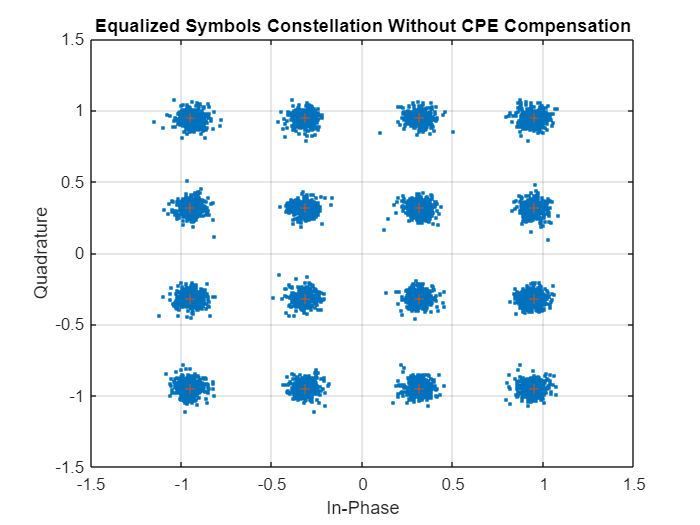

        % Sincronizacion de tiempo
        pathFilters = getPathFilters(Pam_sim.canal);
        [offset,mag] = nrPerfectTimingEstimate(pathGains,pathFilters);

        rxWaveform = rxWaveform(1+offset:end,:);

        %Demodulacion OFDM
        Grilla_Subframe_rx = nrOFDMDemodulate(portadora,rxWaveform);

        if Pam_sim.perfectEstimation


            estChannelGrid = nrPerfectChannelEstimate(portadora,pathGains,pathFilters,offset,sampleTimes);

            %Obtener una estimación perfecta del ruido (a partir de la realización del ruido)

RMS EVM (in percent) for equalized symbols without CPE compensation: 6.276038% 


            noiseGrid = nrOFDMDemodulate(portadora,noise(1+offset:end ,:));
            noiseEst = var(noiseGrid(:));

        else
            [estChannelGrid,noiseEst] = nrChannelEstimate(portadora,rxGrid,dmrsIndices,dmrsSymbols,'CDMLengths',pdsch.DMRS.CDMLengths);
        end


        [pdschRx,pdschHest] = nrExtractResources(Indices_Pdsch,Grilla_Subframe_rx,estChannelGrid);
        [pdschEq,csi] = nrEqualizeMMSE(pdschRx,pdschHest,noiseEst);

        if Param_sim.Compensacion_Fase
            % Inicializar la rejilla temporal para almacenar los símbolos ecualizados
            tempGrid = nrResourceGrid(portadora,pdsch.NumLayers);

            % Extraer símbolos PT-RS de la rejilla recibida y estimada
            [ptrsRx,ptrsHest,~,~,~,ptrsLayerIndices] = nrExtractResources(Indices_ptrs,Grilla_Subframe_rx,estChannelGrid,tempGrid);

            % Ecualizacion de los símbolos PT-RS y asignarlos a tempGrid
            ptrsEq = nrEqualizeMMSE(ptrsRx,ptrsHest,noiseEst);
            tempGrid(ptrsLayerIndices) = ptrsEq;

            % Estimacion del canal residual en las ubicaciones PT-RS en
            % tempGrid
            cpe = nrChannelEstimate(tempGrid,Indices_ptrs,Simbolos_ptrs);

            % Estimacion del angulo de compensacion
            cpe = angle(sum(cpe,[1 3 4]));

            %  Asignacion de los símbolos PDSCH ecualizados a tempGrid
            tempGrid(Indices_Pdsch) = pdschEq;

            % CP en cada símbolo OFDM dentro del rango de referencia
            % PT-RS OFDM 
            if numel(Informacion_Indices_PDSCH.PTRSSymbolSet) > 0
                symLoc = Informacion_Indices_PDSCH.PTRSSymbolSet(1)+1:Informacion_Indices_PDSCH.PTRSSymbolSet(end)+1;

                tempGrid(:,symLoc,:) = tempGrid(:,symLoc,:).*exp(-1i*cpe(symLoc));
            end

            % Extract PDSCH symbols
            pdschEq = tempGrid(Indices_Pdsch);
        end


        % Pam_sim.constPlot.ChannelNames = "Layer "+(pdsch.NumLayers:-1:1);
        % Pam_sim.constPlot.ShowLegend = true;
        % % Constellation for the first layer has a higher SNR than that for the
        % % last layer. Flip the layers so that the constellations do not mask
        % % each other.
        % Pam_sim.constPlot(fliplr(pdschEq));
        eqSymbols = [eqSymbols; pdschEq];

        [bits_received,rxSymbols] = nrPDSCHDecode(portadora,pdsch,pdschEq,noiseEst);
        rxbits = [rxbits,bits_received{1,1}<0]; % Bits decodificados

    end
    N_Wb = Conteo_Bits_Erroneos(txbits,rxbits) % Numero de bits erroneos
    if N_Wb==0
        Ber = 1/length(txbits);
    else 
        Ber = N_Wb/length(txbits)
    end
    ber = [ber,Ber];
end

refSymbols = getConstellationPoints(pdsch);
% Plot constelacion
figure
plot(pdschEq,'.')
hold on
plot(refSymbols,'+')
title('Simbolos ecualizados con compensacion de fase')
grid on
xlabel('In-Phase')
ylabel('Quadrature')
% Display RMS EVM
evm = comm.EVM('ReferenceSignalSource','Estimacion apartir de la constelacion de referencia','ReferenceConstellation',refSymbols);
fprintf('RMS EVM (en porcentaje) para los simbolos con compensacion CPE: %f%% \n',evm(eqSymbols))
% Display bit error rate
% errorRate = nnz(rxbits-txbits)/numel(txbits);
% fprintf('Bit error rate without CPE compensation: %f \n',errorRate)


**Analisis sin compensacion de fase (CPE)**

# **Funciones Empleadas**

function Puntos = Puntos_Referencia(modulacion)
% Calcula los puntos de la constelacion de referencia en el esquema de
% modulacion
switch modulacion
    case "QPSK"
        Cantidad_Puntos = 4;
    case "16QAM"
        Cantidad_Puntos = 16;
    case "64QAM"
        Cantidad_Puntos = 64;
    case "128QAM"
        Cantidad_Puntos = 128;
    case "256QAM"
        Cantidad_Puntos = 256;
end
Val = int2bit(0:Cantidad_Puntos-1,log2(Cantidad_Puntos));
Puntos = nrSymbolModulate(Val(:),modulacion);
end

function sym = getConstellationPoints(pdsch)
%getConstellationPoints Constellation points
%   SYM = getConstellationPoints(PDSCH) returns the constellation points
%   SYM based on modulation schemes provided in PDSCH configuration object.

sym = [];
modulation = string(pdsch.Modulation);  % Convert modulation scheme to string type
ncw = pdsch.NumCodewords;               % Number of codewords
if ncw == 2 && (numel(modulation) == 1)
    modulation(end+1) = modulation(1);
end
% Get the constellation points
for cwIndex = 1:ncw
    qm = strcmpi(modulation(cwIndex),{'QPSK','16QAM','64QAM','256QAM'})*[2 4 6 8]';
    sym = [sym; nrSymbolModulate(int2bit((0:2^qm-1)',qm),modulation(cwIndex))]; %#ok<AGROW>
end

end




function [Bits_errados]=Conteo_Bits_Erroneos(Bits_Tx,Bits_Rx)
%Compara posicion por posicion los bits de 2 vectores columna, realiza un
%conteo de los bits que son diferentes
Bits_errados=0;
for i=1:length(Bits_Tx)
    if Bits_Tx(i)~=Bits_Rx(i)
        Bits_errados=Bits_errados+1;
    end
end

end